# Generación del mandril

- Curva de un cilindro:

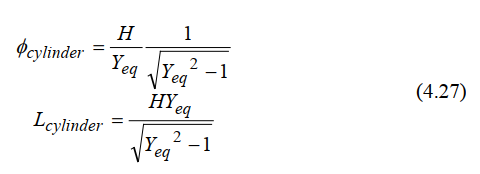

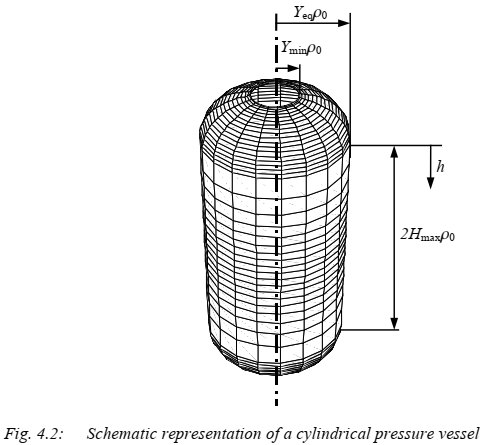

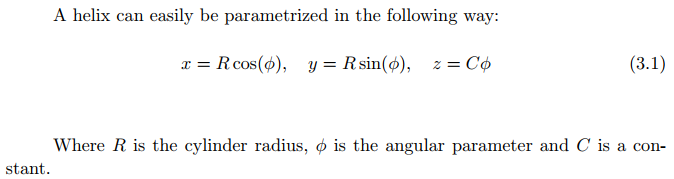

- Curva de un cono:

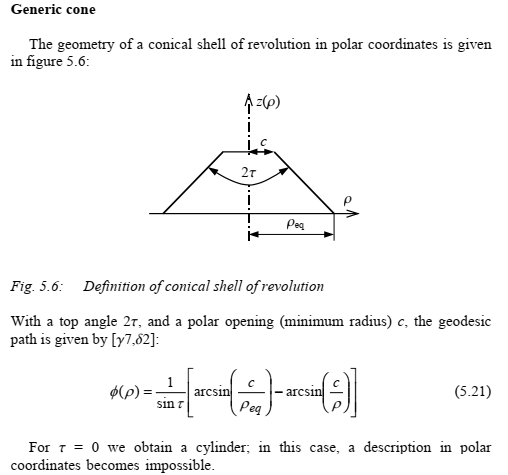

function mandril = generacion_del_mandril(var_ini, vector_calculos_iniciales, excel)
    %Variables de entrada
    dm = vector_calculos_iniciales.dm; 
    lm = vector_calculos_iniciales.lm; 
    rc = vector_calculos_iniciales.rc; % radio menor del cono, que siempre es el izquierdo.
    rfm = var_ini.rfm; % rfm: Radio del mandril en el extremo derecho en mm.
    rim = var_ini.rim; % rim: Radio del mandril en el extremo izquierdo en mm.
    zfm = var_ini.zfm; % zfm: Coordenada del extremo derecho del mandril en mm.
    zim = var_ini.zim; % zim: Coordenada del extremo izquierdo del mandril en mm.
    
    %Inicializamos las variables de salida de la funcion
    celda_mandril = {};
    mandril = struct();

    % Unicamente me define la curva para un cilindro o un cono
    if rim == rfm
        [X, Y, Z, tc] = generador_superficie(rc, rc, zim, zfm);
        %% Superfície parametrizada del mandril en coordenadas esfericas
        %Cilindro
        syms teta phi
        ro = rc / sin(teta);
        Se = [ro * sin(teta) * cos(phi), ro * sin(teta) * sin(phi), ro * cos(teta)]; %Curva de un cilindro
        
        %% Propriedades de la superficie - coordenadas esfericas
        coeficientes_de_Christoffel = funcion_de_Christoffel(Se, phi, teta);
        
        % Escribimos las variables de salida para un cilindro (estructuras y celdas)
        mandril.eteta = coeficientes_de_Christoffel.ev;
        mandril.gteta = coeficientes_de_Christoffel.gv;
        celda_mandril(1, :) = {'eteta', char(mandril.eteta)};
        celda_mandril(2, :) = {'gteta', char(mandril.gteta)};

    else
        [X, Y, Z, tc] = generador_superficie(rim, rfm, zim, zfm);
        %% Superfície parametrizada del mandril en coordenadas polares
        %Cono
        syms phi ro
        z = ro * lm / dm - rim * lm / dm + zim;
        S = [ro * cos(phi), ro * sin(phi), ro * lm / dm - rim * lm / dm + zim];
        %% Propriedades de la superficie - coordenadas polares
        coeficientes_de_Christoffel = funcion_de_Christoffel(S, phi, ro);
        zlinha = diff(z, ro);
        z2linha = diff(zlinha, ro);

        % Escribimos la variable de salida para un cono (estructuras y celdas)
        mandril.ero = coeficientes_de_Christoffel.ev;
        mandril.gro = coeficientes_de_Christoffel.gv;
        mandril.zlinha = zlinha;
        mandril.z2linha = z2linha;
        celda_mandril(3, :) = {'ero', char(mandril.ero)};
        celda_mandril(4, :) = {'gro', char(mandril.gro)};
        celda_mandril(5, :) = {'zlinha', char(mandril.zlinha)};
        celda_mandril(6, :) = {'z2linha', char(mandril.z2linha)};
    end % termina el bloque if

    mandril.ro = ro;
    mandril.chr = coeficientes_de_Christoffel.chr;
    mandril.E = coeficientes_de_Christoffel.E;
    mandril.F = coeficientes_de_Christoffel.F;
    mandril.G = coeficientes_de_Christoffel.G;
    mandril.gg1 = coeficientes_de_Christoffel.gg1;
    mandril.L = coeficientes_de_Christoffel.L;
    mandril.M = coeficientes_de_Christoffel.M;
    mandril.N = coeficientes_de_Christoffel.N;
    mandril.gg2 = coeficientes_de_Christoffel.gg2;
    mandril.e = coeficientes_de_Christoffel.e;
    mandril.g = coeficientes_de_Christoffel.g;
    mandril.efi = coeficientes_de_Christoffel.eu;
    mandril.gfi = coeficientes_de_Christoffel.gu;
    mandril.X = X;
    mandril.Y = Y;
    mandril.Z = Z;
    mandril.tc = tc;
    
    % Escribir una celda, ya que es más fácil exportar un archivo con formato de celdas
    celda_mandril(7, :) = {'ro', char(mandril.ro)};
    celda_mandril(8, :) = {'E', char(mandril.E)};
    celda_mandril(9, :) = {'F', char(mandril.F)};
    celda_mandril(10, :) = {'G', char(mandril.G)};
    celda_mandril(11, :) = {'L', char(mandril.L)};
    celda_mandril(12, :) = {'M', char(mandril.M)};
    celda_mandril(13, :) = {'N', char(mandril.N)};
    celda_mandril(14, :) = {'efi', char(mandril.efi)};
    celda_mandril(15, :) = {'gfi', char(mandril.gfi)};
    celda_mandril(16, :) = {'tc', mandril.tc};
    celda_mandril(17, :) = {'gg1', char(mandril.gg1)};
    celda_mandril(18, :) = {'gg2', char(mandril.gg2)};
    celda_mandril(19, :) = {'e', char(mandril.e(:))};
    celda_mandril(20, :) = {'g', char(mandril.g)};
    % % Escribir un archivo con las variables de entrada
    writecell(celda_mandril, excel, 'Sheet', 'Variables del mandril', 'Range', 'A1');
    writecell({'X'}, excel, 'Sheet', 'Variables del mandril', 'Range', 'A21');
    writematrix(mandril.X(:,:), excel, 'Sheet', 'Variables del mandril', 'Range', 'B21');
    writecell({'Y'}, excel, 'Sheet', 'Variables del mandril', 'Range', 'A23');
    writematrix(mandril.Y(:,:), excel, 'Sheet', 'Variables del mandril', 'Range', 'B23');
    writecell({'Z'}, excel, 'Sheet', 'Variables del mandril', 'Range', 'A25');
    writematrix(mandril.Z(:,:), excel, 'Sheet', 'Variables del mandril', 'Range', 'B25');
    writecell({'chr1'}, excel, 'Sheet', 'Variables del mandril', 'Range', 'A27');
    writematrix(char(mandril.chr(:,:,1)), excel, 'Sheet', 'Variables del mandril', 'Range', 'B27');
    writecell({'chr2'}, excel, 'Sheet', 'Variables del mandril', 'Range', 'A28');
    writematrix(char(mandril.chr(:,:,2)), excel, 'Sheet', 'Variables del mandril', 'Range', 'B28');
end % termina la funcion